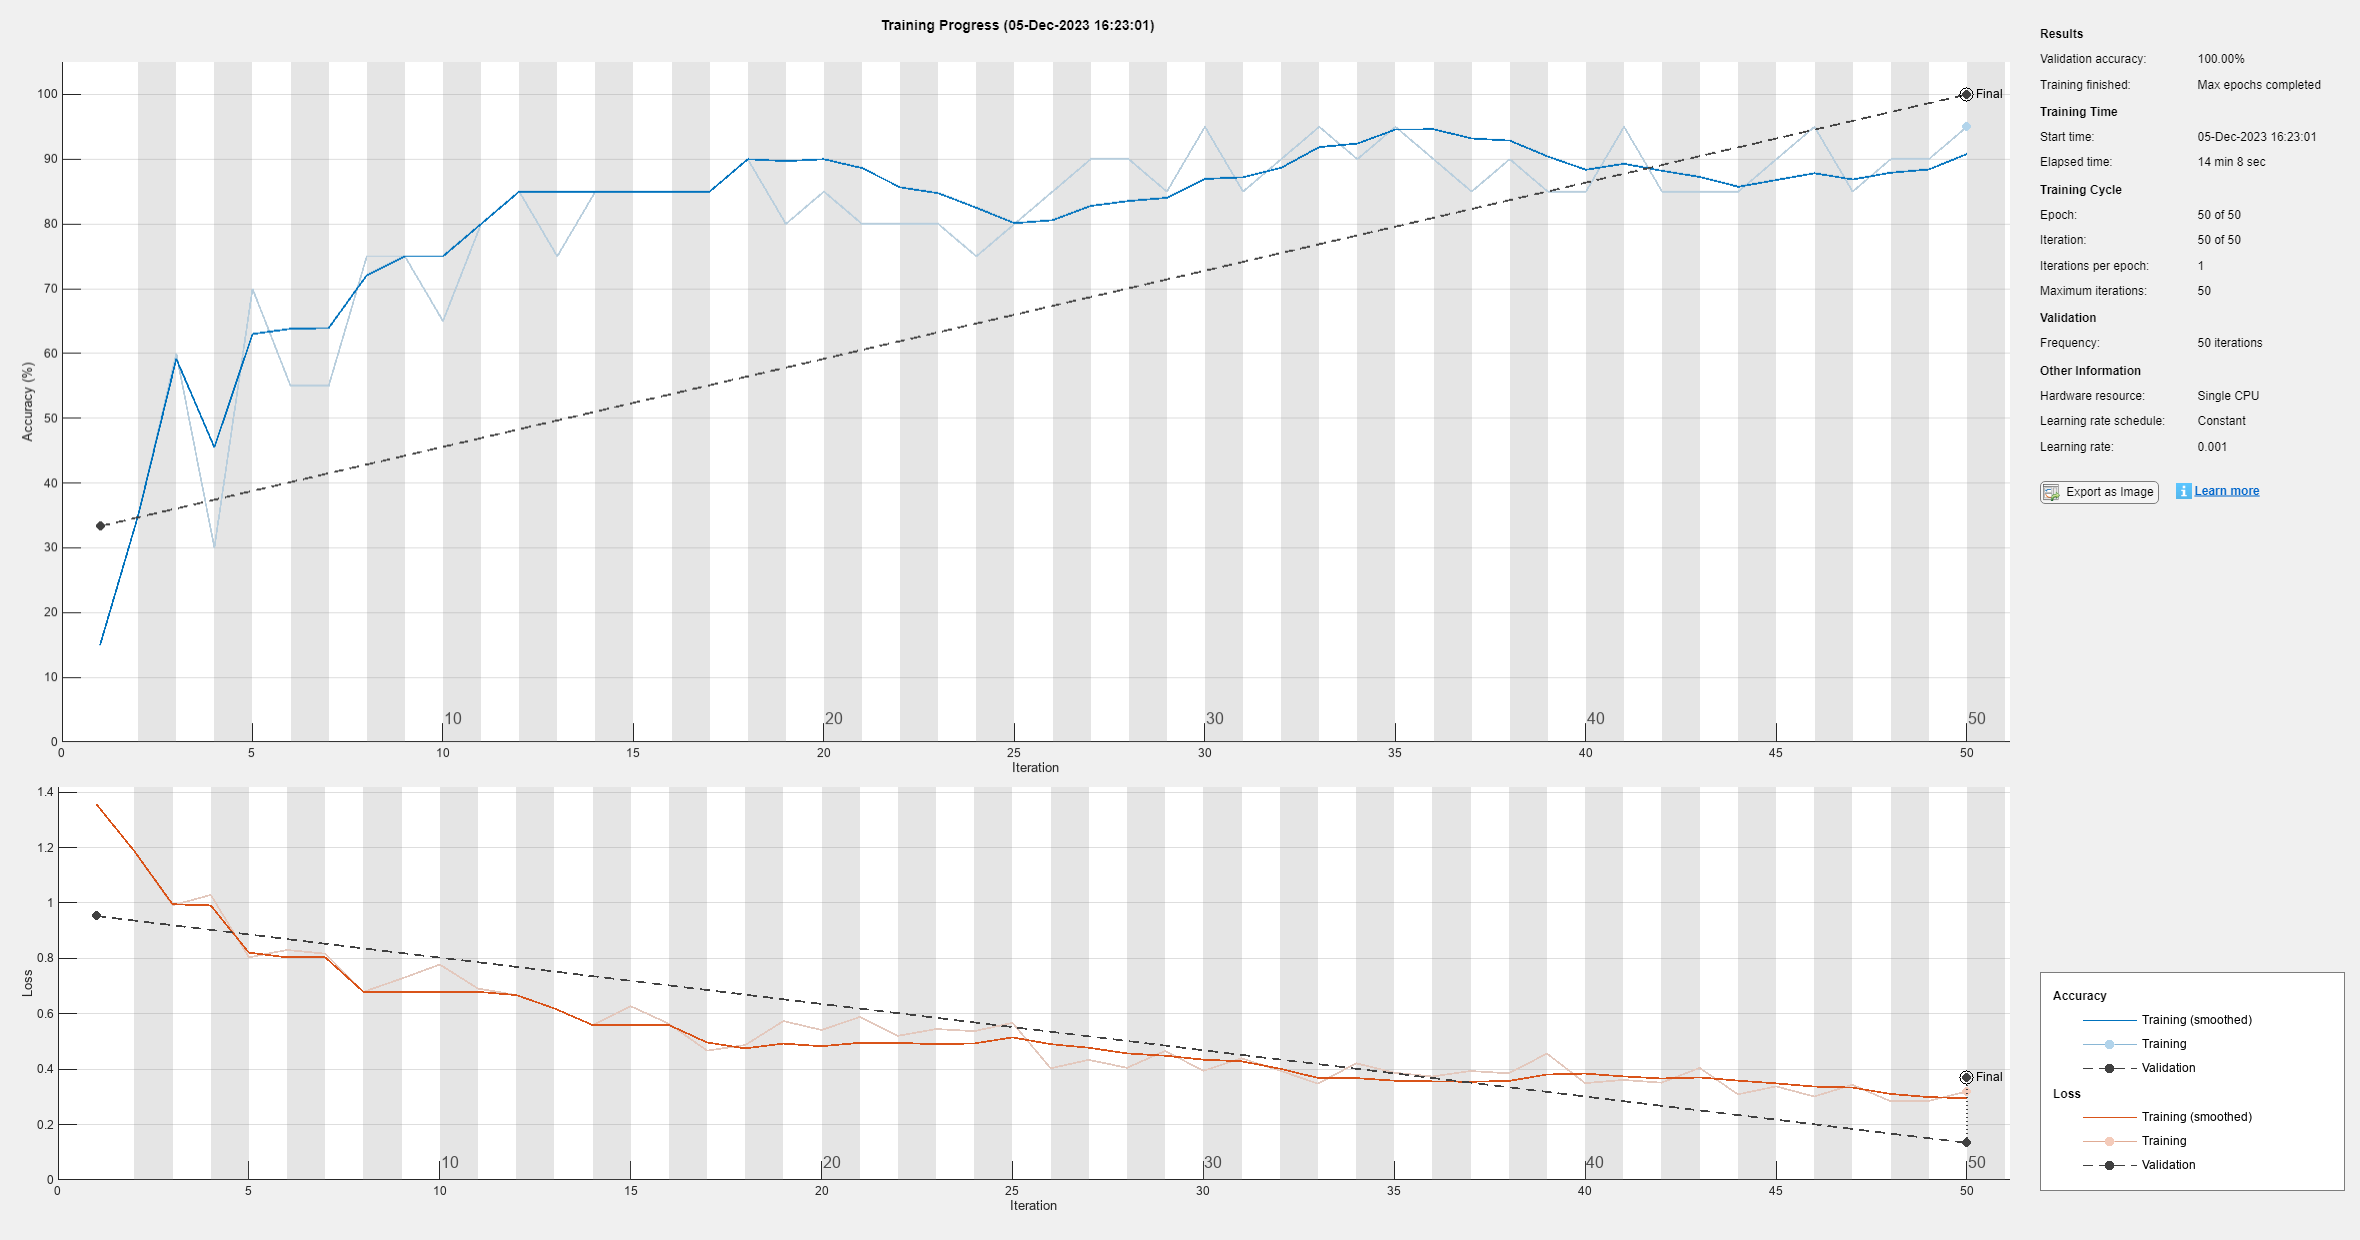



%Applied code example from MATLAB's time-frequency convolutional network

%Reads in baseline data by opening up the folder and all folders in that
%folder
tab = tabularTextDatastore("M:\EEG_DATA", "IncludeSubfolders",true,"FileExtensions",".txt");

%Creates labels for later classfication based on the filename's first letter
labels = filenames2labels(tab.Files,"ExtractBetween",[1 1]);

%Puts those labels into a 1x1 cell
data = cell(numel(labels),1);
ii = 1;

%Iterates through all the data and populates a table
while hasdata(tab)
    tsTable = read(tab);
    ts = tsTable.Var1;
    data{ii} = reshape(ts,1,[]);  
    ii = ii+1;
end

%Sets up the classification labels. File names start with specific letters
%and those correspond to a given category (i.e. normal, siezure, etc)
categLabels = labels;
categLabels = removecats(categLabels,["O","F","S"]);
categLabels(labels == categorical("O")) = categorical("Normal");
categLabels(labels == categorical("F"))  = categorical("Pre-seizure");
categLabels(labels == categorical("S")) = categorical("Seizure");

%Sets up a training set, test set, and validation set. Values were
%suggested by MATLAB's tutorial
idx = splitlabels(categLabels,[0.7 0.2 0.1]);
trainData = data(idx{1});
trainCat = categLabels(idx{1});
testData = data(idx{2});
testCat = categLabels(idx{2});
valData = data(idx{3});
valCat = categLabels(idx{3});

%takes the inverse of the number of categories, prevents bias toward
%underrepresented class 
weights = numel(categLabels)./(3*countcats(categLabels));

%Each function is explained above it

net = [sequenceInputLayer(1,"MinLength",4096,"Name","input","Normalization","zscore")
    %Applies 1-d convolution filter to the 1 dimensional intput data is in,
    %stride downsamples data along time dim by 2
    convolution1dLayer(5,1,"stride",2)
    %Part of the deep learning toolbox, creates CWT layer of 1024 samples
    cwtLayer("SignalLength",2048,"IncludeLowpass",true,"Wavelet","amor")
    maxPooling2dLayer([5,10])
    convolution2dLayer([5,10],5,"Padding","same")
    maxPooling2dLayer([5,10])  
    batchNormalizationLayer
    reluLayer
    convolution2dLayer([5,10],10,"Padding","same")
    maxPooling2dLayer([2,4])   
    batchNormalizationLayer
    reluLayer
    flattenLayer
    globalAveragePooling1dLayer
    dropoutLayer(0.4)
    fullyConnectedLayer(3)
    softmaxLayer
    classificationLayer("Classes",unique(trainCat),"ClassWeights",weights)
    ];

%Max epochs and min batch size were kept small b/c of ufapps computing
%limitations. These can be increased for more accurate classification
%adam = Adaptive moment estimation = stochastic solver
options = trainingOptions("adam", ...
    "MaxEpochs",50, ...
    "MiniBatchSize",20, ...
    "Shuffle","every-epoch",...
    "Plots","training-progress",...
    "ValidationData",{valData,valCat},...
    "L2Regularization",1e-2,...
    "OutputNetwork","best-validation-loss",...
    "Verbose", false);

%Trains the neural network based on previous options 
trainNet = trainNetwork(trainData,trainCat,net,options);


%Saves the neural network to be used later
save trainNet;

